%----------------------------------------------------------------%
% Live script to generate Data for Cognitive Radar Research
% Metacognition system to descriminate clutter disrtibutions
% Author: Geoffrey Dolinger (uses function CLutterSimNG by Alexander Stringer)
% Creation Date: 8/14/2022 
%----------------------------------------------------------------%

% Set Up Parameters for Data Generation with function ClutterSimNG
clear all
close all
data_num = 20000;                                                    % Number of samples
order_count=64;                                                     % Number of Ordered Statistics
bins=50;                                                            % Number of Bins in Histograms
max_hist = 8;                                                       % Histograms range from -max_hist/bins to max_hist
sample_len = 16;                                                    % Sample length
train_samples = 32;                                                 % # of training samples (sample_len*train samples determine sample length)
rho=0.9;                                                            % Rho for clutter sim
                                                               % Shape Parameter
b=1;                                                                % Texture Partameter
range= linspace(-max_hist/bins,max_hist,bins);                      % Range for Histogram
type = {'gaussian','K','K','K','pareto1','pareto1','pareto1'};      % List types of length n for data generation
a=[1,0.55,2.375,6.09,1.4,4.75,8.75];                                % list of shape parameters size n
labels=[0,1,2,3,4,5,6];                                             % list of labels

%Generate Data based on above lists
data_sim = zeros(data_num,sample_len*train_samples);
data_full = zeros(length(a),data_num,sample_len*train_samples);
data_order = zeros(length(a),data_num,order_count);
data_out = zeros(length(a),data_num,order_count+2);
data_hist = zeros(length(a),data_num,bins);
data_stats = zeros(length(a),data_num,4);
data_label = zeros(length(a),data_num);
for i = 1:length(a)                                                                           % Shape Parameter
    data_label(i,:) = labels(i);
    for k=1:data_num
        data_sim(k,:) = reshape(ClutterSimNG(type{i},train_samples,train_samples, sample_len, rho, a(i), b),1,train_samples*sample_len);         % Complex Data
    end
%     for j=1:data_num
%         data_train = data_set(j:j+train_samples-1,:);
%         data_sim(j,:) = data_train(:)';
%     end    
    data_full(i,:,:) = data_sim;
    data_order (i,:,:) = order_stats(abs(data_sim),order_count);                                  % ordered statistics
    d_mean = mean(abs(data_sim),2);                                                    % Mean of each sample
    d_std = std(abs(data_sim),0,2);                                                    % Std of each sample
    d_skw = skewness(abs(data_sim),0,2);                                                    % Skewness of each sample
    d_kts = kurtosis(abs(data_sim),0,2);                                                    % Kurtosis of each sample
    
    data_hist(i,:,:) = histc(abs(data_sim),range,2) ;                                            % Histogram of samples
    data_stats(i,:,:) = cat(2,d_mean,d_std,d_skw,d_kts);
    data_out(i,:,:) = cat(2,squeeze(data_order(i,:,:)),d_mean,d_std);                                    % Data to send to ML as input data
end

%Build a List of Data samples to perform Jensen-Shannon Divergence
%calculation and supply mean and std matricies. (List matching the
%classification to ML core)
dist_list = cell(1,length(a));
plot_label = cell(1,length(a));
hist_temp = zeros(data_num,bins);
for i=1:length(a)
    hist_temp = squeeze(data_hist(i,:,:));
    dist_list{i} = hist_temp./(sample_len*train_samples);
    if strcmp(type{i},'gaussian')
        plot_type = 'G';
    elseif strcmp(type{i},'K')
        plot_type = 'K';
    else
        plot_type = 'P';
    end
    plot_label{i} = sprintf('%s(%.3f)',plot_type,a(i));
end
[JS_mean,JS_std] = JS_matrix(dist_list)  

JS_mean =     0.0159    0.1299    0.0746    0.2417    0.0441    0.1701    0.2995
    0.1299    0.0308    0.1895    0.3464    0.1151    0.0698    0.1063
    0.0746    0.1895    0.0284    0.1039    0.0553    0.2649    0.3782
    0.2417    0.3464    0.1039    0.0296    0.1808    0.4435    0.5288
    0.0441    0.1151    0.0553    0.1808    0.0319    0.1541    0.2647
    0.1701    0.0698    0.2649    0.4435    0.1541    0.0144    0.0526
    0.2995    0.1063    0.3782    0.5288    0.2647    0.0526    0.0107


JS_std =     0.0062    0.0370    0.0242    0.0367    0.0154    0.0380    0.0382
    0.0370    0.0128    0.0457    0.0469    0.0364    0.0241    0.0294
    0.0242    0.0457    0.0086    0.0308    0.0216    0.0436    0.0411
    0.0367    0.0469    0.0308    0.0074    0.0423    0.0363    0.0283
    0.0154    0.0364    0.0216    0.0423    0.0100    0.0391    0.0427
    0.0380    0.0241    0.0436    0.0363    0.0391    0.0072    0.0232
    0.0382    0.0294    0.0411    0.0283    0.0427    0.0232    0.0064


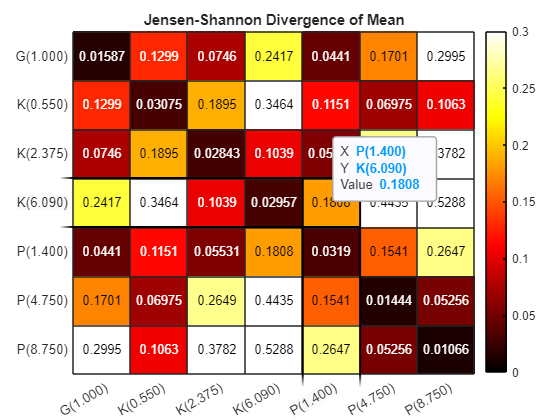

%Plot and format heat map for ML matching List
figure(1)
h=heatmap(JS_mean);
h.XData=plot_label;
h.YData=plot_label;
h.Colormap = hot;
h.ColorLimits=[0 0.3];
h.Title = 'Jensen-Shannon Divergence of Mean';

% Given the number of classes, generate the labels for the ML training
classes=length(a);                                                                  % Number of classes
data = reshape(data_order(1:classes,:,:),data_num*classes,order_count); 
label = reshape(data_label(1:classes,:),data_num*classes,1);
save('clutter_order_7a.mat','data', 'label') 

Unrecognized function or variable 'gauss_hist'.

function [rank_x] = order_stats(x,k)                    % Ordered statistics function.  
[n1,n2]=size(x);                                        % Determine input size
sort_x = sort(x,2);                                     % Sort each sample          
rank_x = zeros(n1,k);                                   % Build rank matrix
span=(n2-1)/(k-1);                                      % Calculate the index span for internal ordered values
spans = 0:1:(k-1);                                      % develop the indexes for ordered stats
set_span = int64(spans*span+1);                         % truncate to integers for ordered stats index
for i=1:k                                               % loop all indexes to build ordered statictics
    rank_x(:,i)=sort_x(:,set_span(i));
end
end

function [Dkl_PQ] = KBLV(P,Q)                           % Kullback Leiber function (expects normalized histograms)
Dkl_PQ=zeros(size(P,1),1);                              % Build empty vector for each sample
P=P+eps;                                                % Ensure no divide by 0 error
Q=Q+eps;                                                % Ensure no divide by 0 error                                            
for i=1:size(P,2)
    Dkl_PQ = Dkl_PQ+ P(:,i).*log(P(:,i)./Q(:,i));       % Calculate Prob(P)*ln (Prob(P)/Prob(Q))
end
end

function [JS] = JenShan(P,Q)                            % Jensen-Shannon Divergence Function
M = .5.*(P+Q);                                          % Calculate M
JS = .5.*KBLV(P,M)+.5.*KBLV(Q,M);                       % Generate symetrical divergence given P and Q
end

function [JS_mean,JS_std]= JS_matrix(dist_list)         % Build the matrix of JS mean and STD given a dictionary of histograms
JS_mean = zeros(size(dist_list,2),size(dist_list,2));   % Build empty mean matrix
JS_std = zeros(size(dist_list,2),size(dist_list,2));    % Build empty std matrix
for i=1:size(dist_list,2)                               % loop list twice (all combinations)
    for j = 1:size(dist_list,2)
        if i==j                                         % for diagonal, shuffle the samples so it is not directly score of 0.
            temp_dist = dist_list{i};
            rand_dist = temp_dist(randperm(size(temp_dist, 1)), :); % shuffle samples.
            JS_mean(i,j) = mean(JenShan(dist_list{i},rand_dist));   % Calculate diagonal mean
            JS_std(i,j) = std(JenShan(dist_list{i},rand_dist));     % Calculate diagonal std
        else
            JS_mean(i,j) = mean(JenShan(dist_list{i},dist_list{j}));% Calculate non-diagonal mean
            JS_std(i,j) = std(JenShan(dist_list{i},dist_list{j}));  % Calculate non-diagonal std
        end
    end
end
end